answersOn = true;

# Final Exam Review ICP-3

# Frequency Domain Convolution

Convolution can be done in either the time domain or the frequency domain.  The equivalent of performing time domain convolution is to find the DFT of each sequence using the FFT and multiplying them point by point.  Each sequence must be padded to at least the length that would result from the time domain convolution.  However, the FFT often requires a length of a power of 2.  So the sequences are padded to a length that is the next power of 2.

In the file 'ICP_1.mat' there are two variables "inputSignal" and "impulseResponse".  

A) Load the file.  Find the lengths of the input signal and the impulse response.  Then plot both signals in the time domain

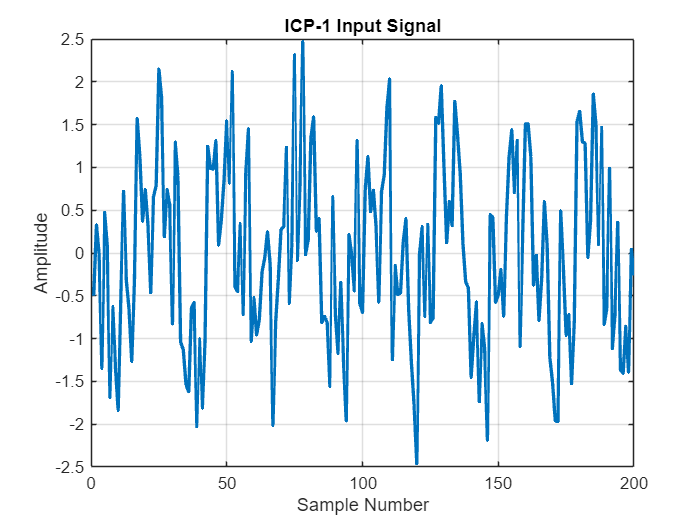

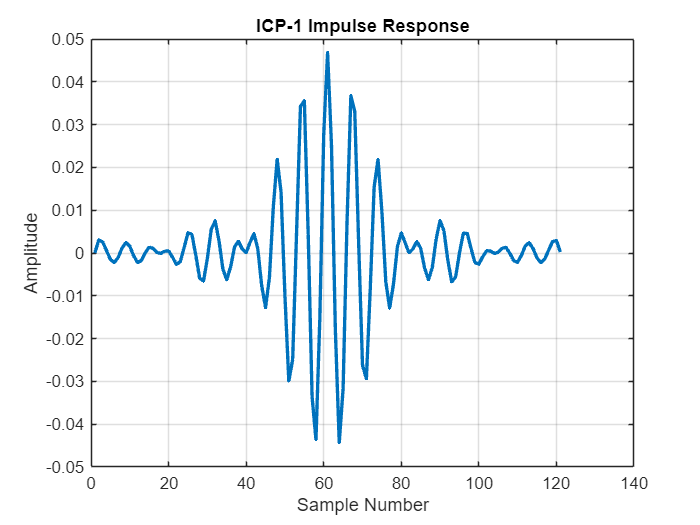

clearvars -except answersOn

if answersOn
        
    fName = 'ICP_1.mat';
    pName = pwd;
    load(fullfile(pwd,fName));
    
    signalLength = length(inputSignal);
    impulseLength = length(impulseResponse);
    
    figure
    plot(inputSignal,'LineWidth',2)
    grid on
    title('ICP-1 Input Signal')
    xlabel('Sample Number')
    ylabel('Amplitude')
    
    figure
    plot(impulseResponse,'LineWidth',2)
    grid on
    title('ICP-1 Impulse Response')
    xlabel('Sample Number')
    ylabel('Amplitude')
    
end

B)  What is the length of the convolution of the input signal with the impulse response?

%  The length of the convolution is the sum of the lengths of both
%  sequences minus 1.   M+N-1

if answersOn
    
    convLength = signalLength + impulseLength - 1;
    
    
    fprintf('The length of the convolution of both sequences is %3.2f', convLength)
    
    
end

The length of the convolution of both sequences is 320.00

C)  What length must the FFT be padded to to perform convolution in the frequency domain?

%  The FFT must be a power of two, so pad each sequence to the next largest
%  power of two if it is not already a power of 2

padLength = 2^(ceil(log2(convLength)));

if answersOn
    
    fprintf('The FFT needs to be padded to a length of %3d',padLength);
end

The FFT needs to be padded to a length of 512

D)  Find the FFT of each sequence and plot the magnitude.  The FFT of the signal is the frequency spectrum of the signal.  The FFT of the impulse response is the frequency response of the filter.   After viewing the spectrum and the filter frequency response, what would you expect the output of the filter to look like in the frequency domain?

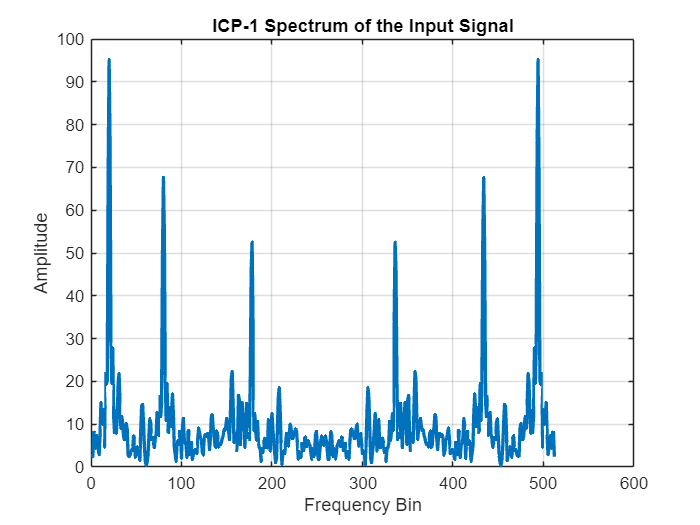

%  Find the FFT of each sequence padded to the correct length

fftInput = fft(inputSignal, padLength);
fftImpulse = fft(impulseResponse, padLength);

%  Since we don't know the sampling frequency just plot against the sample
%  number which is the frequency bin

figure
plot(abs(fftInput),'LineWidth',2)
grid on
title('ICP-1 Spectrum of the Input Signal')
xlabel('Frequency Bin')
ylabel('Amplitude')

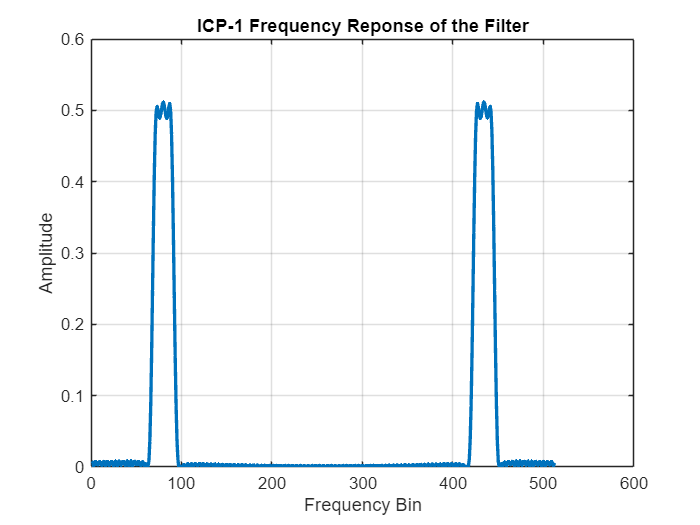



figure
plot(abs(fftImpulse),'LineWidth',2)
grid on
title('ICP-1 Frequency Reponse of the Filter')
xlabel('Frequency Bin')
ylabel('Amplitude')

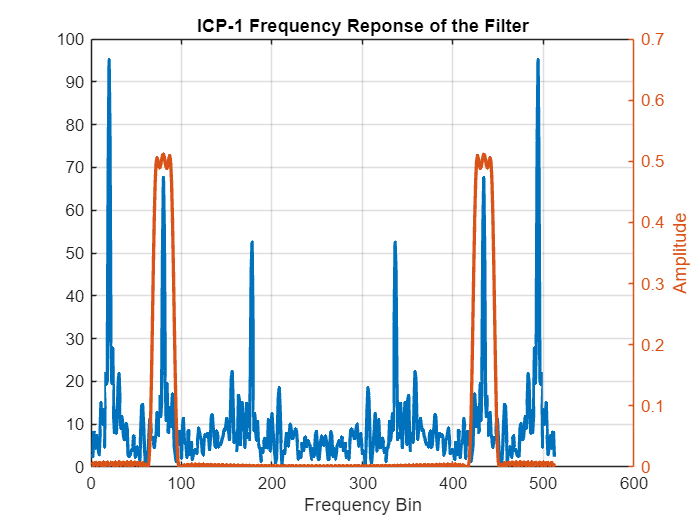

figure
bins = [0:length(fftInput)-1];


plot(abs(fftInput),'LineWidth',2)
yyaxis right
plot(abs(fftImpulse),'LineWidth',2)

grid on
title('ICP-1 Frequency Reponse of the Filter')
xlabel('Frequency Bin')
ylabel('Amplitude')

D)  Perform frequency domain convolution.  Multiply the two FFT's point by point.  Plot the magnitdue of the result.  This is the frequency spectrum of the result of the convolution.  Is this what you expected?

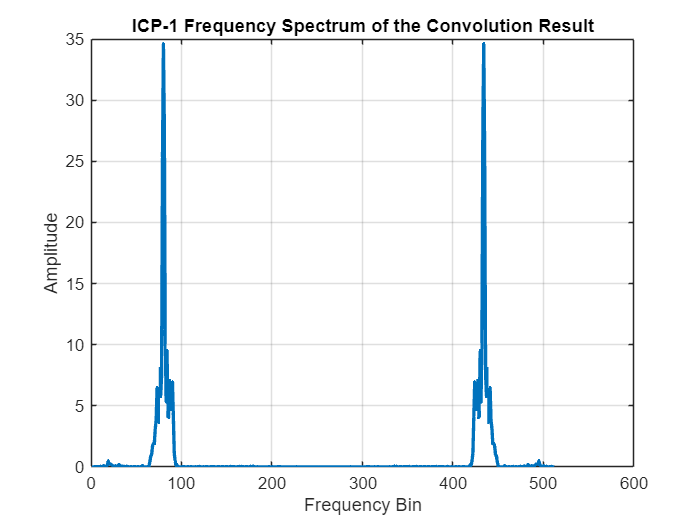

%  Perform frequency domain convolution

%  Find the FFT of each sequence padded to the correct length

fftInputPad = fft(inputSignal, padLength);
fftImpulsePad = fft(impulseResponse, padLength);

%  Multiply the two FFT's point by point

fftResult = fftInputPad .* fftImpulsePad;

%  Plot the result of the convolution in the frequency domain

figure
plot(abs(fftResult),'LineWidth',2)
grid on
title('ICP-1 Frequency Spectrum of the Convolution Result')
xlabel('Frequency Bin')
ylabel('Amplitude')

E)  Take the IFFT of the resulting sequence.  Truncate that result to the length of the convolution.  Plot the time domain result of the convolution done in the frequency domain

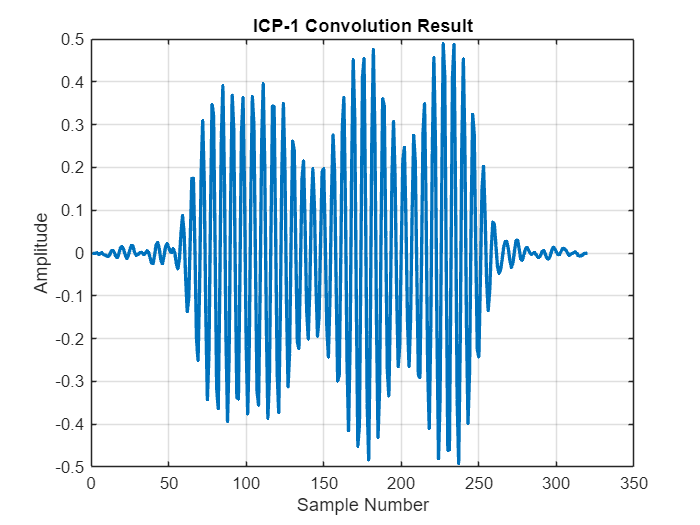


%  Find the IFFT of the result and truncate to the length of the
%  convolution

invFFT = ifft( fftResult );
convResult = invFFT( 1:convLength );


%  Plot the result of the convolution in the time domain

if answersOn
    
    
    %  Plot the result of the convolution
    figure
    plot( convResult,'LineWidth',2 );
    grid on
    title('ICP-1 Convolution Result')
    xlabel('Sample Number')
    ylabel('Amplitude')
    
    
    
end

# Final Exam Review ICP-4

# The Windowed SINC Filter (Tutorial)

A windowed SINC filter starts with a SINC function that is truncated to a desired length.  The corner frequency is found as a fraction of the sampling rate as it is with most of the filters we have worked with.  The SINC function is computed as


$$h[i] = \frac{sin(2\pi f_c i)}{i\pi}$$


It looks like this for a length 51 filter with a corner frequency, fc of 0.25

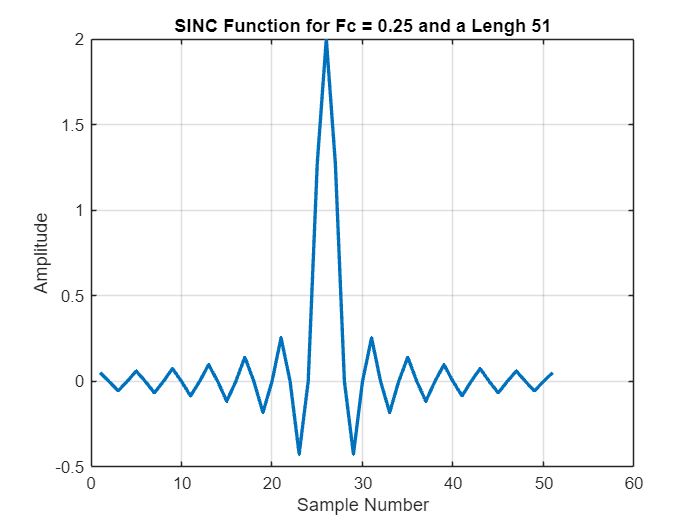

clearvars -except answersOn

i = [-25:25];
fc = 0.25;
hSinc = sinc(2*fc*i)/(2*fc);

figure
plot(hSinc,'LineWidth',2)
grid on
title('SINC Function for Fc = 0.25 and a Lengh 51')
xlabel('Sample Number')
ylabel('Amplitude')

Then the sequence is multiplied point by point with a windowing function.  Two common windows are the Hamming Window and the Blackman Window.

The equation for the Hamming window is defined as


$$w[i] = 0.54 - 0.46cos(\frac{2\pi i}{M})$$


and it looks like this for a length of 51

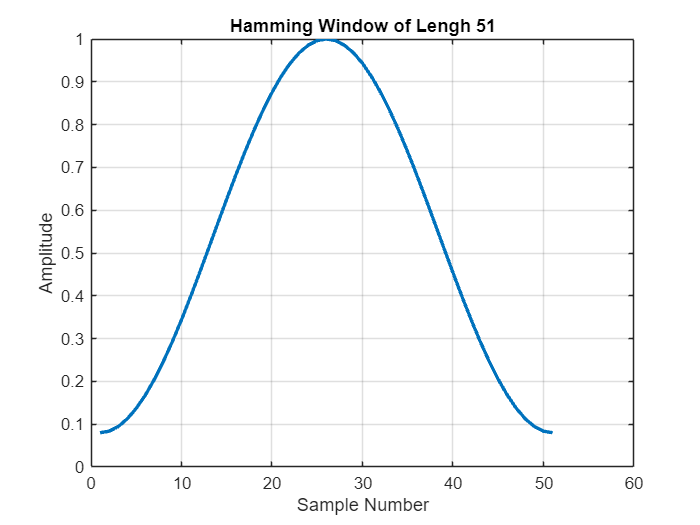

figure
plot(hamming(51),'LineWidth',2)  % Built in MATLAB function for the Hamming window
grid on
title('Hamming Window of Lengh 51')
xlabel('Sample Number')
ylabel('Amplitude')

The equation for the Blackman window is defined as


$$w[i] = 0.42 - 0.5 cos(\frac{2\pi i}{M}) +0.08cos(\frac{4\pi i}{M}) $$


and it looks like this for a length of 51

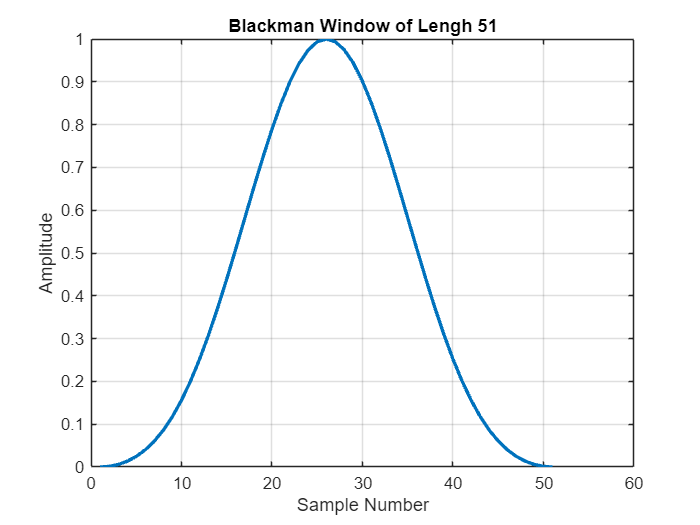

figure
plot(blackman(51),'LineWidth',2)  %  Built in MATLAB function for the Blackman Window
grid on
title('Blackman Window of Lengh 51')
xlabel('Sample Number')
ylabel('Amplitude')

The filter impulse response is computed by multiplying the window point by point with the SINC sequence.  The plot below shows the windowed SINC result and its FFT for the frequency response.

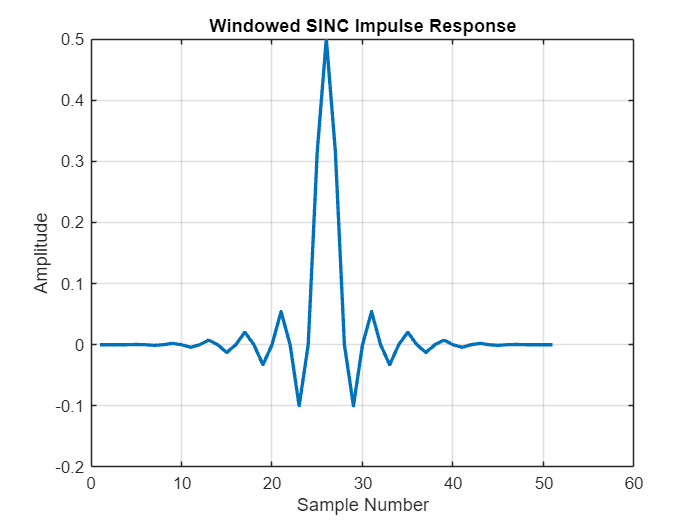

%  Point by Point multiplication of the SINC and the window
%  Transpose the blackman window result to get them both the be row
%  vectors.

windowedSINC = hSinc .* blackman(51)'; 

%  Set the gain to 1 by dividing by the sum of the impulse response

windowedSINC = windowedSINC / sum( windowedSINC );

figure
plot(windowedSINC,'LineWidth',2)  
grid on
title('Windowed SINC Impulse Response')
xlabel('Sample Number')
ylabel('Amplitude')

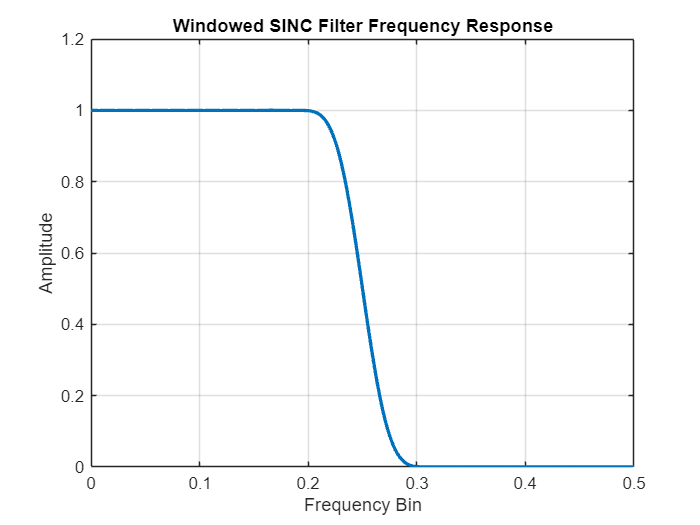

%  Find the frequency resonse using 1024 sample points

freqResponse = fft(windowedSINC,1024);
freqVector = [0:1023]/1024;

figure
plot(freqVector, abs(freqResponse),'LineWidth',2)  
grid on
title('Windowed SINC Filter Frequency Response')
xlabel('Frequency Bin')
ylabel('Amplitude')
xlim([0,0.5])

# Final Example ICP-4

# Windowed SINC Filters using FIR_Designer.m

The function FIR_Designer.m can be used to easily find the impulse response of a Windowed SINC filter

The basic function call is shown below where nOrder is the length of the filter and cutBPM is the corner frequency for a sampling rate of 600 BPM.  The returned variable hSINC will be the floating point coefficients of a windowed SINC filter that can be used in MATLAB for futher computation

Other options are shown in the figure below

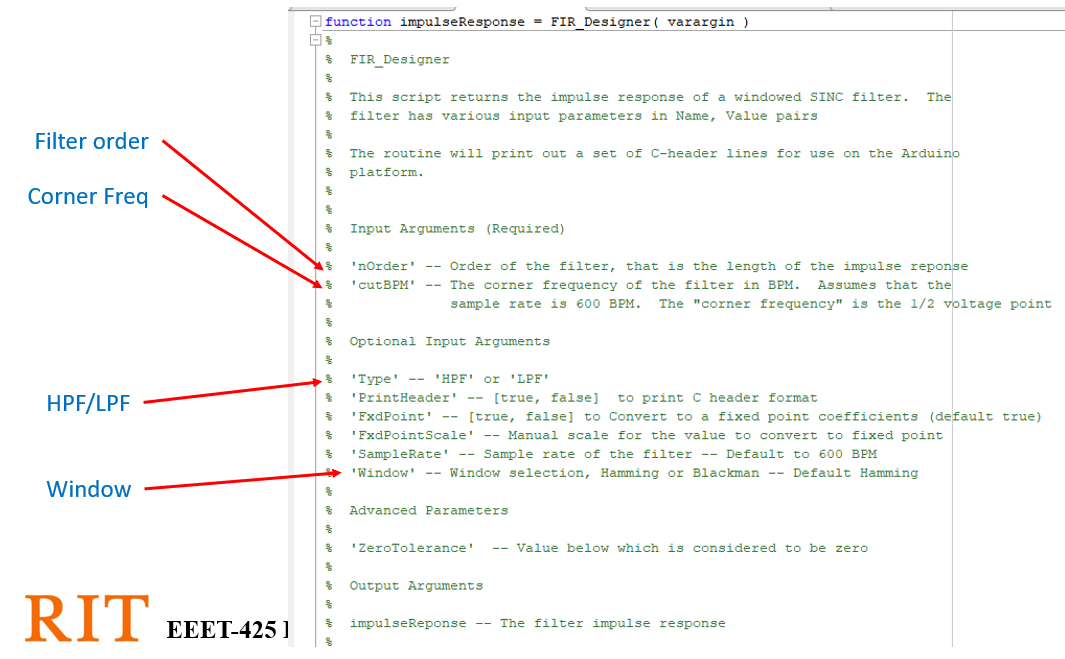

A)  Using the FIR designer find the impulse response of a windowed SINC low pass filter with a corner frequency of 30 BPM with transition region that is  10 BPM wide.  Recall that the transition region is from 0.9 to 0.1 of the filter frequency response.

h = [-0.001733, -0.001987, -0.002422, -0.002671, -0.002119, 0.000000, 0.004438, 0.011742, 0.022082, 0.035129, 0.050032, 0.065489, 0.079916, 0.091684,...
0.099386, 0.102066, 0.099386, 0.091684, 0.079916, 0.065489, 0.050032, 0.035129, 0.022082, 0.011742, 0.004438, 0.000000, -0.002119, -0.002671,...
-0.002422, -0.001987, -0.001733];


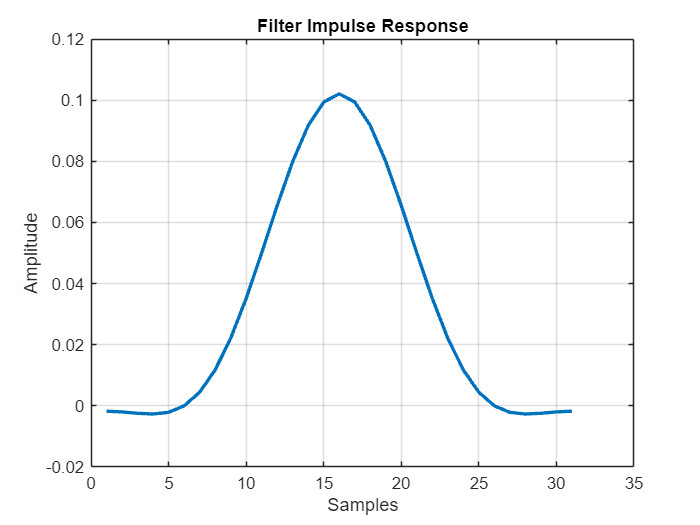

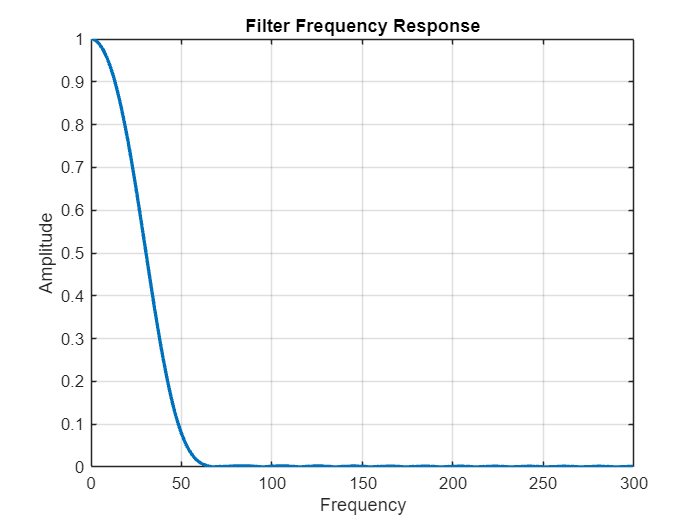

clearvars -except answersOn


fcLPF = 30;
lpfLength = 31;   %  Start with 31 and check the response

%  User FIR_Designer.  Turn off the header printout

hLPF = FIR_Designer('nOrder',lpfLength, 'cutBPM', fcLPF, 'PrintHeader',false);

h = [-0.000463, -0.000453, -0.000403, -0.000312, -0.000177, 0.000000, 0.000214, 0.000453, 0.000697, 0.000918, 0.001083, 0.001155, 0.001102, 0.000896,...
0.000527, -0.000000, -0.000654, -0.001381, -0.002106, -0.002737, -0.003174, -0.003323, -0.003106, -0.002475, -0.001424, 0.000000, 0.001699, 0.003522,...
0.005278, 0.006748, 0.007712, 0.007967, 0.007358, 0.005804, 0.003312, -0.000000, -0.003908, -0.008085, -0.012118, -0.015538, -0.017859, -0.018616,...
-0.017417, -0.013977, -0.008160, 0.000000, 0.010283, 0.022292, 0.035467, 0.049125, 0.062500, 0.074807, 0.085294, 0.093305, 0.098328, 0.100039,...
0.098328, 0.093305, 0.085294, 0.074807, 0.062500, 0.049125, 0.035467, 0.022292, 0.010283, 0.000000, -0.008160, -0.013977, -0.017417, -0.018616,...
-0.017859, -0.015538, -0.012118, -0.008085, -0.003908, -0.000000, 0.003312, 0.005804, 0.007358, 0.007967, 0.007712, 0.006748, 0.005278, 0.003522,...
0.001699, 0.000000, -0.001424, -0.002475, -0.003106, -0.003323, -0.003174, -0.002737, -0.002106, -0.00

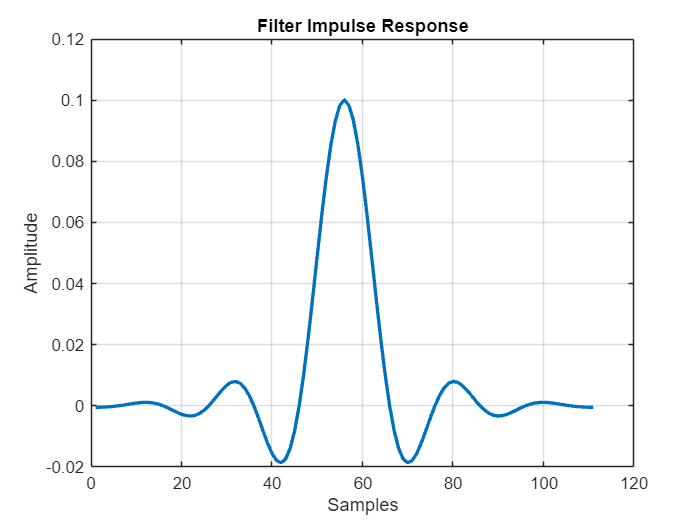

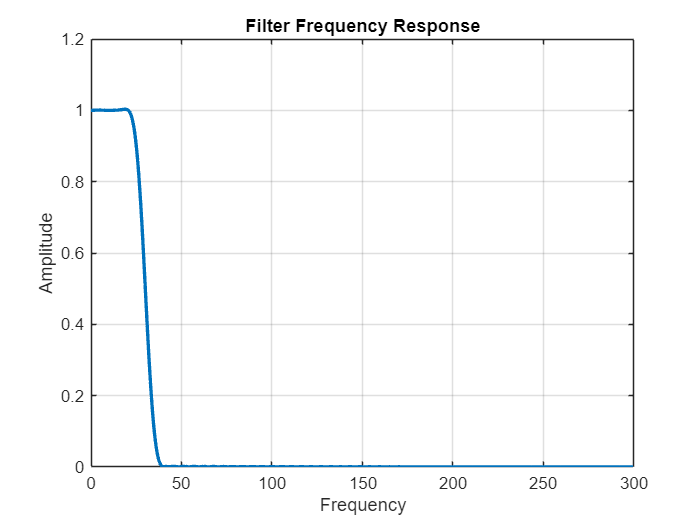

fcLPF = 30;
lpfLength = 111;   %  Iterated through a few options and settled on this.

%  User FIR_Designer.  Turn off the header printout

hLPF = FIR_Designer('nOrder',lpfLength, 'cutBPM', fcLPF, 'PrintHeader',false);

# Final Exam ICP 5 -- Moving Average Filter

## Moving average filter N = 21

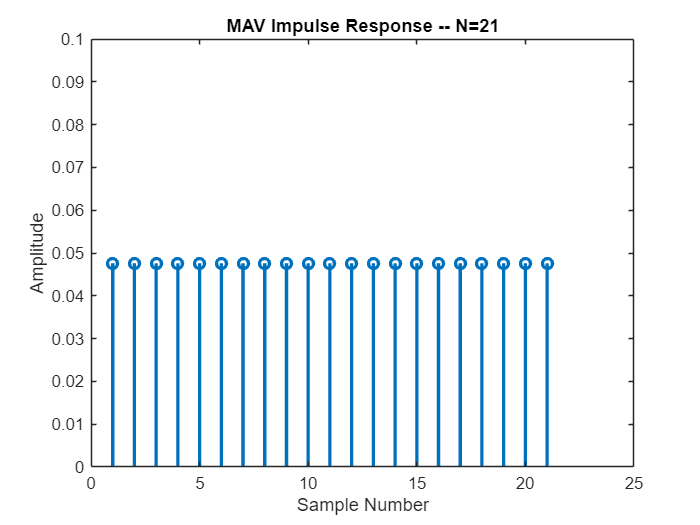


N = 21;
hMav = ones(N,1)/N;

figure
stem(hMav,'LineWidth',2)
title('MAV Impulse Response -- N=21')
xlabel('Sample Number')
ylabel('Amplitude')
ylim([0,.1])

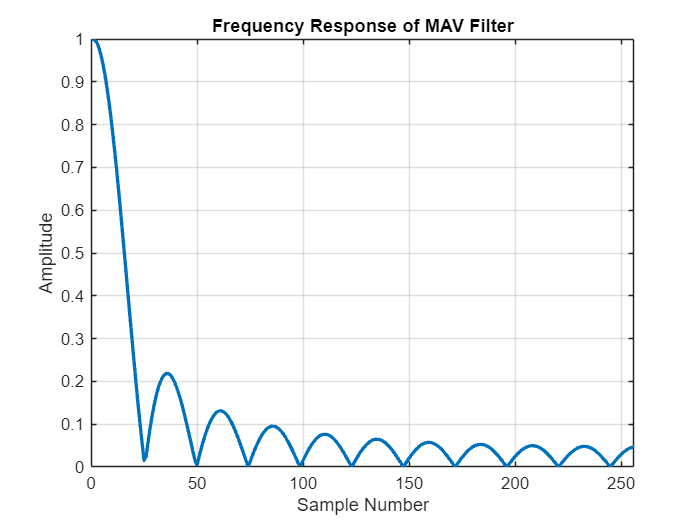


figure
plot(abs(fft(hMav, 512)),'LineWidth',2)
grid on
title('Frequency Response of MAV Filter')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,256])

# Final Exam ICP-6 Properties of Convolution

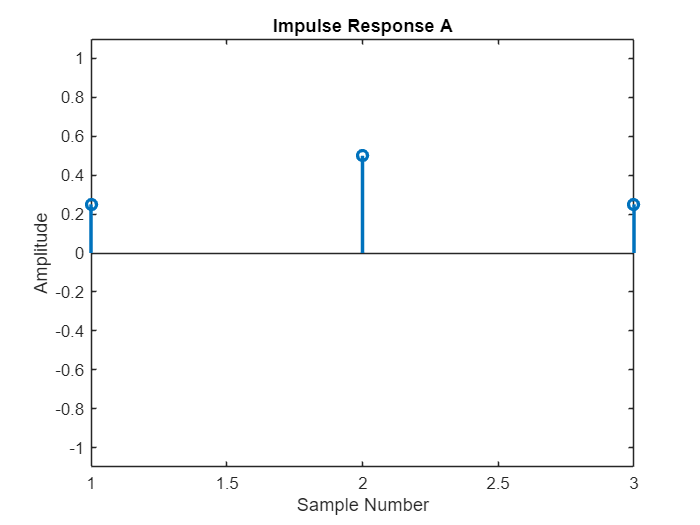



a = [0.25, .5, 0.25];
b = [-1, 1, 0];


figure
stem(a,'LineWidth',2)
title('Impulse Response A')
xlabel('Sample Number')
ylabel('Amplitude')
ylim([-1.1,1.1])

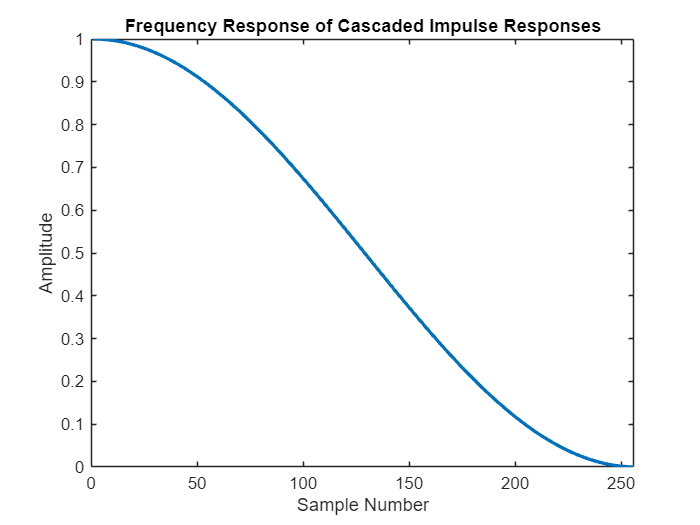



figure
plot(abs(fft(a, 512)),'LineWidth',2)
title('Frequency Response of Cascaded Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,256])

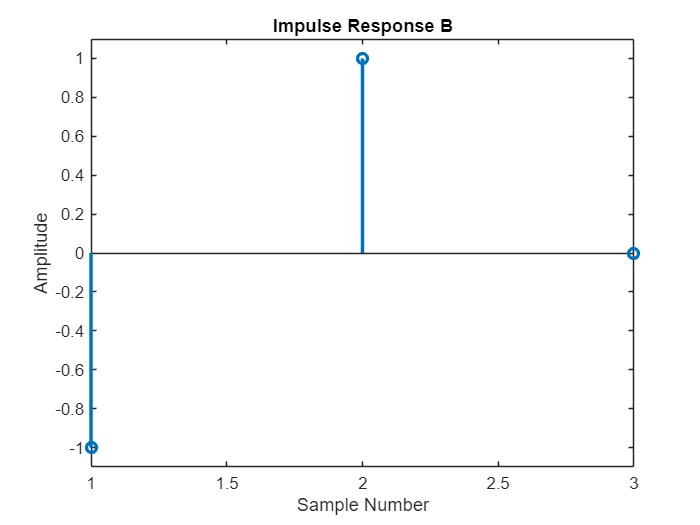



figure
stem(b,'LineWidth',2)
title('Impulse Response B')
xlabel('Sample Number')
ylabel('Amplitude')
ylim([-1.1,1.1])

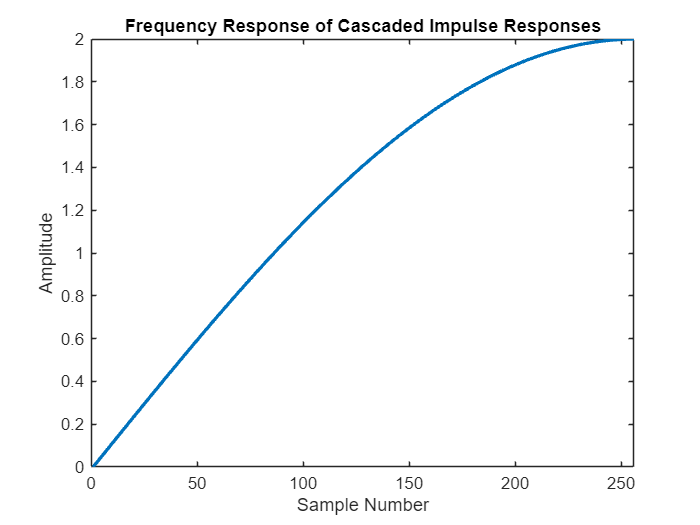



figure
plot(abs(fft(b, 512)),'LineWidth',2)
title('Frequency Response of Cascaded Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,256])

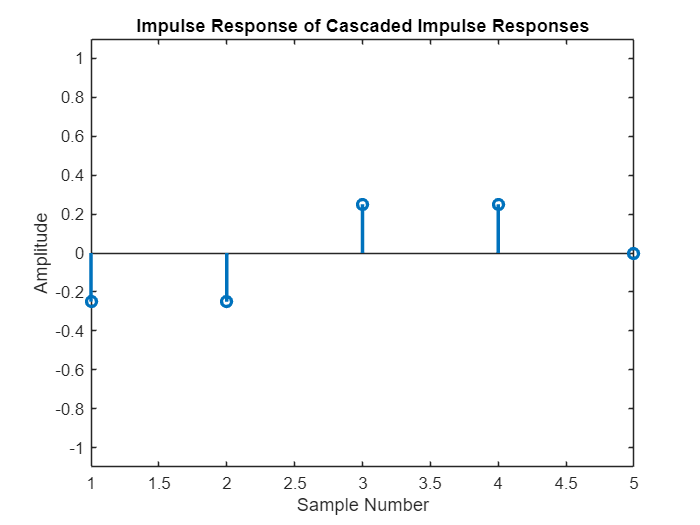



%  Cascaded response


cascade = conv(a, b);
figure
stem(cascade,'LineWidth',2)
title('Impulse Response of Cascaded Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
ylim([-1.1,1.1])

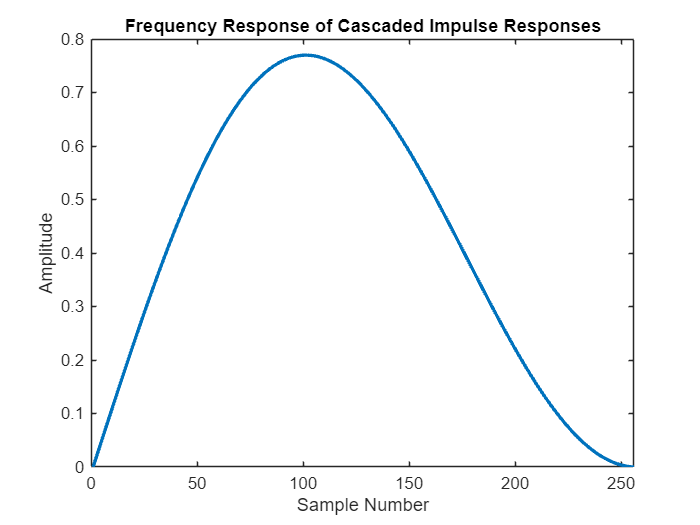


figure
plot(abs(fft(cascade, 512)),'LineWidth',2)
title('Frequency Response of Cascaded Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,256])

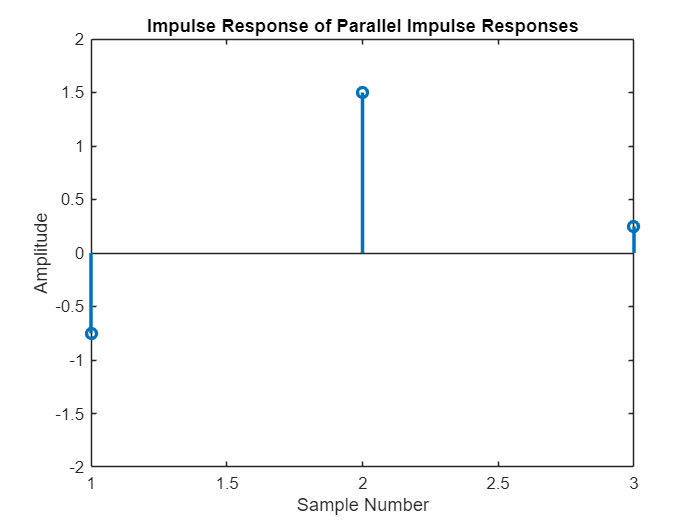



parallel = a+b;
figure
stem(parallel,'LineWidth',2)
title('Impulse Response of Parallel Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
ylim([-2,2])

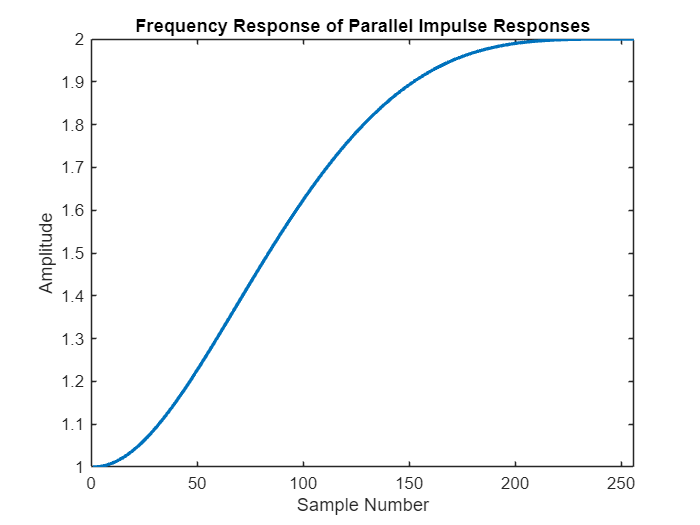



figure
plot(abs(fft(parallel, 512)),'LineWidth',2)
title('Frequency Response of Parallel Impulse Responses')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,256])

# Final Exam Review ICP-7

# Single Pole IIR LPF and HPF

A single pole IIR filter is analogous to a simple RC filter in the analog domain.  The time constant of the digital filter is found from the relative corner frequency of the filter.  Recall that the relative corner frequency of the filter is the corner frequency divided by the sample rate.

### 
$$d = \frac{1}{2\pi f_c }$$


With a step input from 0 to A, the filter output will increase from 0 to 0.632A of its final value in one time constant.  With a step decrease from A to 0 the filter output will decrease from its initial value of A to 0.368A in one time constant.  The time constant may be a fraction, but we can't have fractions of samples.  If the time constant is a fraction then the sample just before the time constant and just after the time constant will be above and below the value of 0.368A.  The same is true on the rising signal.

The amount of decay in just one sample is found using

### $x = e^{-1/d}$ or $x = e^{-2\pi f_c}$

### LOWPASS Filter

The low pass filter is implemented as a difference equation

#### $y_n = a_0 x_n + b_1y_{n-1}$ where x is the input sequence to the filter.

The values of $b_1$and $a_0$ are found using the value x, the amount of decay in one sample time

#### Where $b_1 = x$ and $a_0 = 1-x$

#### The transfer function is $H(z) = \frac{a_0}{1-b_1z^{-1}}
$

### A)  Design a single pole IIR filter with a corner frequency of 250 Hz.  The sampling rate of the system is 8000 Hz.  Plot the impulse response and the frequency response of the filter.

%  Design the single pole IIR filter

%  SOLUTION

fCorner = 250;
fSample = 8000;

fC = fCorner/fSample;

%  Find the value of x from the corner frequency

x = exp(-2*pi*fC);

%  Find the value of b1 and a0

b1 = x;
a0 = 1-x;

%  Find the impulse response using impz.  The numerator of the transfer
%  function is

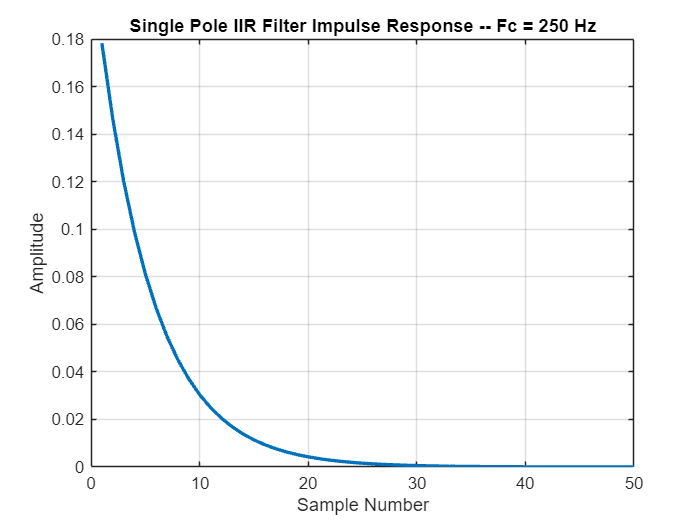


num = a0;
den = [1, -b1];
impulseResponse = impz(num, den, 50);

figure
plot(impulseResponse,'LineWidth',2)  
grid on
title('Single Pole IIR Filter Impulse Response -- Fc = 250 Hz')
xlabel('Sample Number')
ylabel('Amplitude')

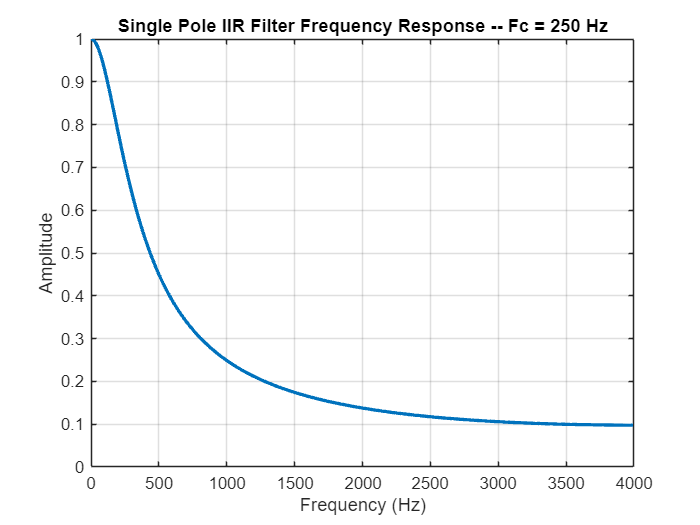

%  Find the frequency response using freqz

[frequencyResponseMag, freqReponseFreq] = freqz( num, den, 512 );
freqVector = freqReponseFreq/(2*pi) * fSample;

figure
plot(freqVector, abs(frequencyResponseMag),'LineWidth',2)  
grid on
title('Single Pole IIR Filter Frequency Response -- Fc = 250 Hz')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

## High Pass Filter

The single pole IIR High pass filter is found in a similar manner.  Again the value of x is computed from

## $x = e^{-1/d}$ or $x = e^{-2\pi f_c}$

The transfer function for the high pass filter has an additional term in the numerator 

## 
$$H(z) = \frac{a_0 + a_1 x_{n-1}}{1-b_1z^{-1}}
$$


and the difference equation is 

## 
$$y_n = a_0 x_n + a_1x_{n-1}+ b_1y_{n-1}$$


The values of $b_1$and $a_0$ are found using the value x, the amount of decay in one sample time

Where 

## 
$$b_1 = x$$
 

## 
$$a_0 = (1+x)/2$$


and 

## 
$$a_1 = -a_0 = -(1+x)/2$$


### B)  Find the impulse and frequency response of a single pole IIR High pass filter with a corner of 1000 Hz in a system with a sampling frequency of 8000 Hz

%  Design the single pole IIR HPF filter.  Fc = 1000 Hz, Fs = 8000 Hz

%  SOLUTION

fCornerHPF = 1000;
fSample = 8000;

fC = fCornerHPF/fSample;

%  Find the value of x from the corner frequency

x = exp(-2*pi*fC);

%  Find the value of b1 and a0

b1 = x;
a0 = (1+x)/2;
a1 = -a0

a1 = -0.7280

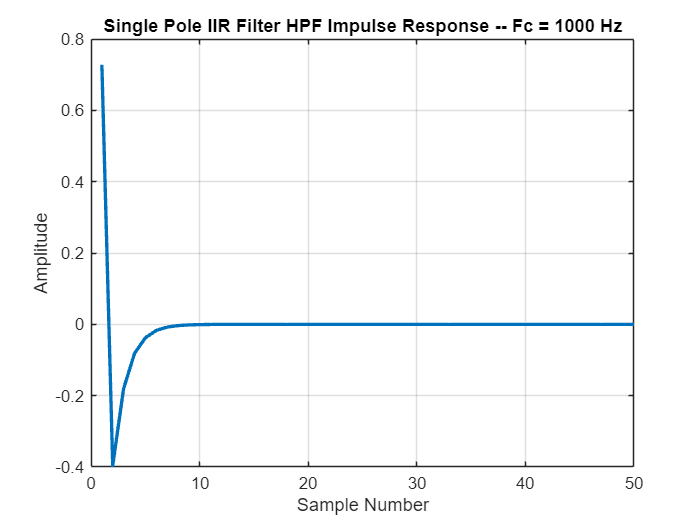



%  Find the impulse response using impz.  The numerator of the transfer
%  function is

num = [a0, a1];
den = [1, -b1];
impulseResponseHPF = impz(num, den, 50);

figure
plot(impulseResponseHPF,'LineWidth',2)  
grid on
title('Single Pole IIR Filter HPF Impulse Response -- Fc = 1000 Hz')
xlabel('Sample Number')
ylabel('Amplitude')

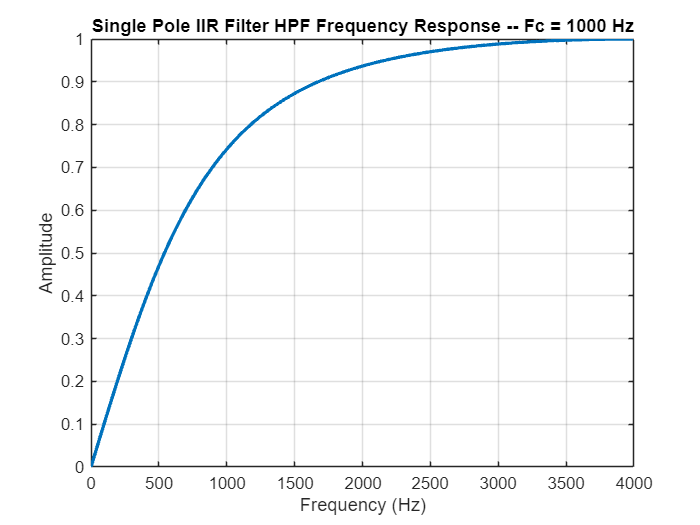




%  Find the frequency response using freqz

[frequencyResponseMag, freqReponseFreq] = freqz( num, den, 512 );
freqVector = freqReponseFreq/(2*pi) * fSample;

figure
plot(freqVector, abs(frequencyResponseMag),'LineWidth',2)  
grid on
title('Single Pole IIR Filter HPF Frequency Response -- Fc = 1000 Hz')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

# Final Exam Review  ICP-8

# Sampling and Aliasing

A sine wave of 6500 kHz is being sampled at a sampling rate of 8 kHz.  After sampling at what positive frequencies will the first 4 copies of the sinusoids be located?

Sampling causes copies of the signal to be created at intervals of the sampling rate.  The positive frequencies that the 6.5 kHz signal will be copied to are

6.5 kHz  + 8 kHz = 14.5 kHz

14.5 kHz + 8 kHz = 22.5 kHz 

6.5 kHz - 8 kHz = -1.5 kHz

-1.5 kHz - 8 kHz = -9.5 kHz

and so forth

There is a negative frequency component at -6.5 kHz and this will be repeated every 8 kHz as well

-6.5 kHz + 8 kHz = 1.5 kHz

1.5 kHz + 8 kHz = 9.5 kHz

-6.5 khz - 8 kHz = -14.5 kHz

-14.5 kHz - 8 kHz = -22.5 kHz

The first 4 positive frequencies are then 1.5 kHz, 6.5 kHz, 9.5 kHz and 14.5 kHz.  Because the sample rate isn’t high enough to sample a 6 kHz signal aliasing occurs and alias signals at 2 kHz and 10 kHz result.

Here is a demonstration of aliasing

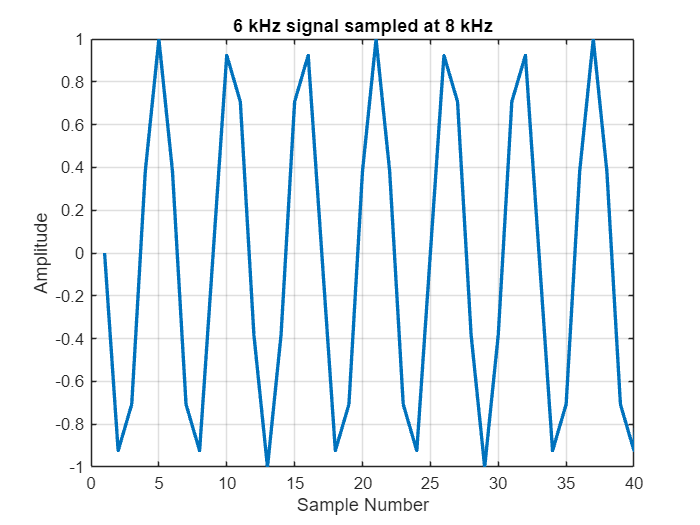

clearvars -except answersOn

%  Sampling with aliasing demonstration

fSample = 8000;
fSignal = 6500;


%  Generate a 6.5 kHz sine wave sampled at 8 kHz


%  Create a vector of sample numbers 0, 1, 2, 3,...
numSamples = 1024;
sampleNumbers = [0:1023]';

%  Create a sine wave at the signal frequency   s[i] = sin( 2*pi * fSig/fSample * i )

sineSignal = sin( 2*pi * fSignal/fSample * sampleNumbers);


figure
plot(sineSignal,'LineWidth',2)  
grid on
title('6 kHz signal sampled at 8 kHz')
xlabel('Sample Number')
ylabel('Amplitude')
xlim([0,40])

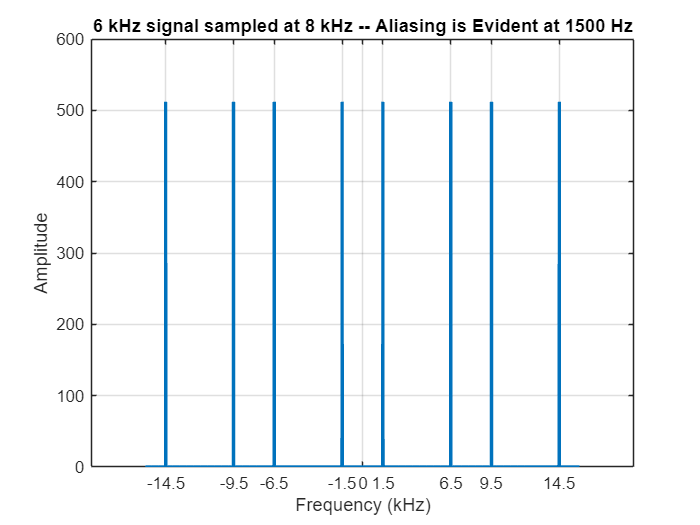

%
%  Plot the frequency spectrum
%


freqSpectrum = fft( sineSignal );
freqVector = [0:numSamples-1]/numSamples * fSample;

%  The frequency spectrum is periodic at the sample rate so concatenate the
%  spectra

freqFull = [freqSpectrum.', freqSpectrum.',freqSpectrum.', freqSpectrum.'];
freqVector = [0:numSamples*4-1]/numSamples * fSample - 2*fSample;


figure
plot(freqVector/1e3, abs(freqFull),'LineWidth',2)
grid on
title('6 kHz signal sampled at 8 kHz -- Aliasing is Evident at 1500 Hz')
xlabel('Frequency (kHz)')
ylabel('Amplitude')
hAx = gca;
hAx.XTick = [-14.5, -9.5, -6.5, -1.5,0, 1.5, 6.5, 9.5, 14.5];

# Final Exam Review ICP-9

# ADC Sampling and Quantization Noise

(Seealso  problem 10 from Exam #1 Practice Problems)

I’m sampling a sinewave with an amplitude of 100 mVrms.  The sinewave has a noise level of 2.9 mVrms on it.  I plan on sampling the signal with an ADC that has an input range of -3V to +3V.  What resolution ADC do I need to degrade the signal to noise ratio by no more than 8 dB?

A)  Find the SNR of the input signal

clearvars -except answersOn
%

%
% The level of my desired signal is the standard deviation of the sinewave.
% The rms voltage of a sinewave is equivalent to its standard deviation.
% The noise level is the standard deviation of the noise.  The SNR is then

stdSignal = 100e-3;  %  Signal standard deviation (RMS level)
stdNoise = 2.9e-3;   %  Noise standard deviation (RMS level)

%  Compute the SNR .  Use 20 log because SNR is the ratio of variances.  You
%  need to square the standard deviation to get the variance

snrSignal = 20*log10( stdSignal / stdNoise );

if answersOn
    fprintf('The SNR is %3.2f dB', snrSignal);
end

The SNR is 30.75 dB

B)  Find the maximum amount of quantization noise that will degrade the SNR by 8 dB.  That is how much noise could be added and keep the SNR to greater than the SNR - 8 dB?

% Since the signal level doesn’t change calculate what the degraded noise level would be.
% The standard deviation of the signal is 100e-3

snrDegradedDb = snrSignal - 8;

%  Find the numerical value of the degraded SNR
snrDegradedNum = 10^(snrDegradedDb /20);

%  Find the total noise in the degraded signal
stdTotalNoise = stdSignal / snrDegradedNum;

%  Then knowing that noise adds in quadrature find out how much noise could
%  be added to get the total noise

%  stdTotalNoise = sqrt(  stdNoise^2 + stdQuantization^2  )  Solve for
%  stdQuantization

stdQuantization = sqrt(stdTotalNoise^2 - stdNoise^2 );

if answersOn
    fprintf(['The degraded SNR is %3.2f dB\n',...
        'The numerical value of the degraded SNR is %3.2f\n',...
        'The standard deviation of the total noise is %3.2f mVRMS\n',...
        'The most quantization noise that can be added is %3.4f mvRMS'],...
        snrDegradedDb,snrDegradedNum, stdTotalNoise/1e-3, stdQuantization/1e-3);
end

The degraded SNR is 22.75 dB
The numerical value of the degraded SNR is 13.73
The standard deviation of the total noise is 7.28 mVRMS
The most quantization noise that can be added is 6.6823 mvRMS

C)  What resolution ADC is required to keep the quantization noise less than the maximum allowed?

%  The standard deviation of the quantization noise is 
%
%  stdQ_ADC = 0.29 * codeValue
%
%  The codeValue is the full scale ADC level divided by 2^N-1 where N is
%  the number of bits
%
%  Solve for the number of bits
%
%  N = log2( 0.29 * ADC_Full_Scale / stdQuantization + 1 )

N = log2( 0.29 * 6 / stdQuantization + 1);

%  Then find the next largest integer number of bits

nBits = ceil( N );

if answersOn
    
    fprintf( ['The computed number of bits is %3.3f\n',...
        'The next largest integer is %3d bits'],...
        N, nBits)
end

The computed number of bits is 8.030
The next largest integer is   9 bits

# Final Exam Review -- ICP-10

# Higher Order Recursive Filters

#### Use the IIR Designer tool to design the filter and then get numerator and denominator coefficients for use in MATLAB

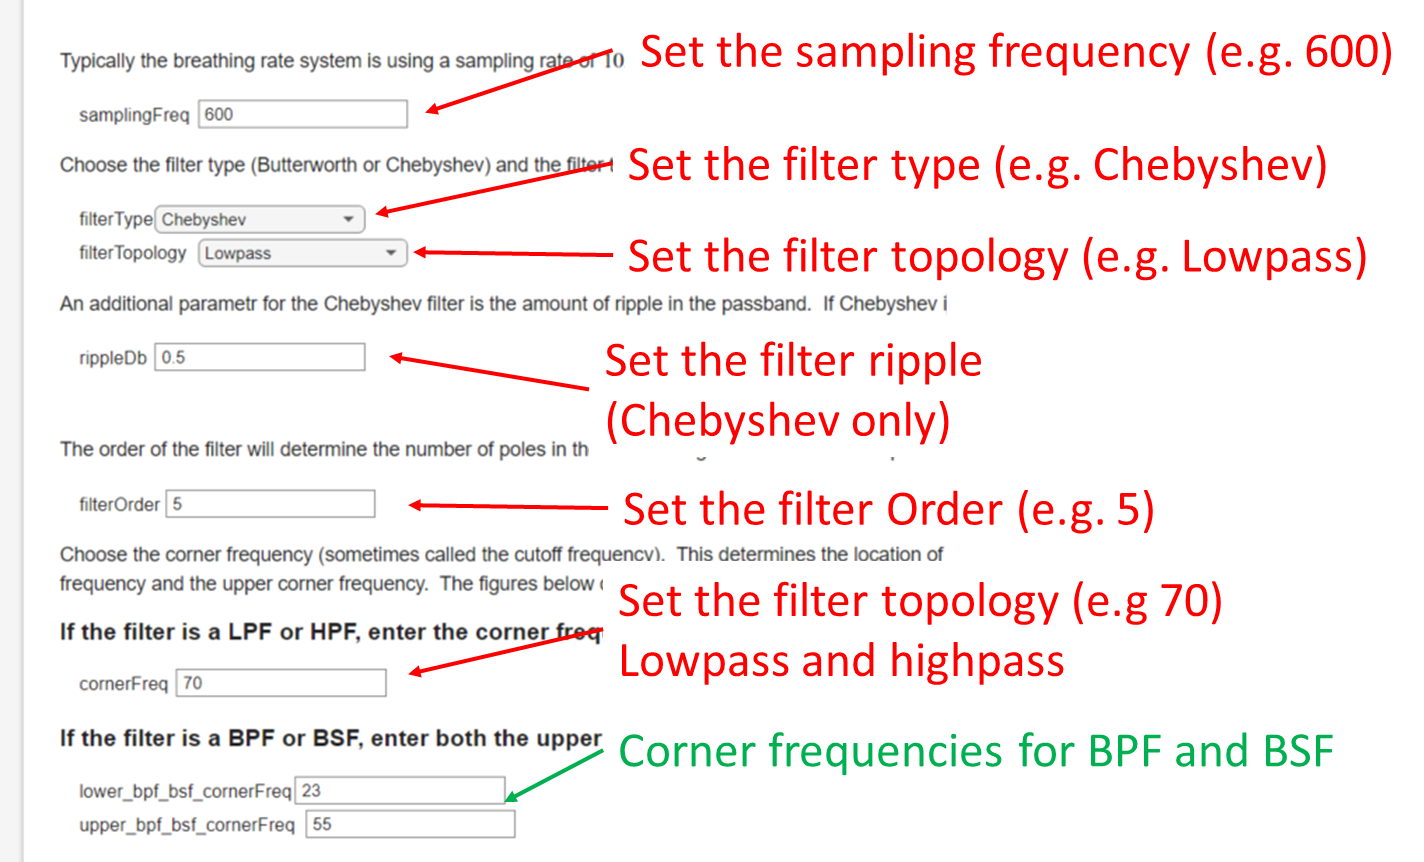

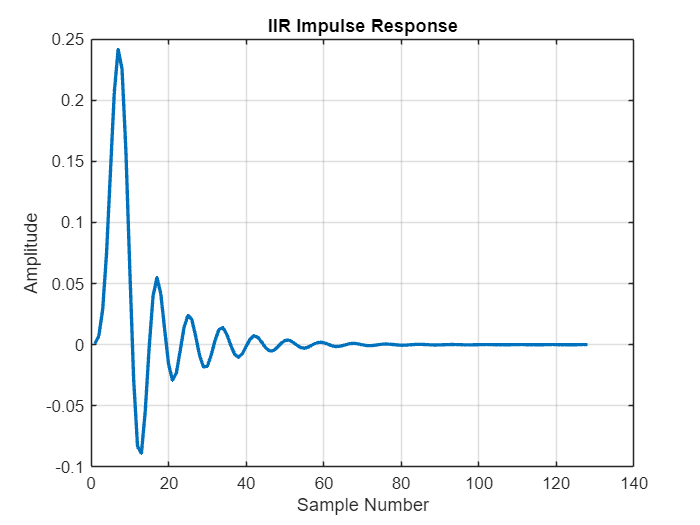



% Numerator and Denominator Coefficients from MATLAB IIR_Designer.mlx

b = [0.0008160, 0.0040802, 0.0081603, 0.0081603, 0.0040802, 0.0008160];
a = [1.0000000, -3.5596819, 5.5972100, -4.7578789, 2.1711919, -0.4247281];


%  Find the Impulse response using impz function in MATLAB
impulseResponse = impz(b,a,128);

%  Plot the impulse response
figure
plot(impulseResponse,'LineWidth',2)
grid on
title('IIR Impulse Response')
xlabel('Sample Number')
ylabel('Amplitude')

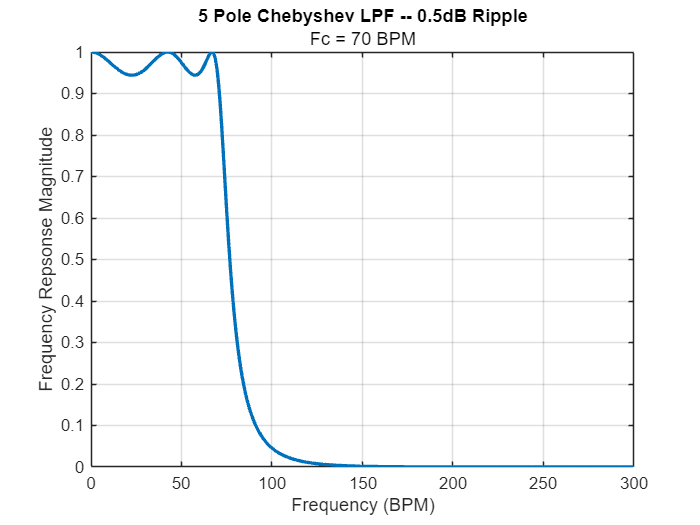

%  Find the frequency response using freqz
%
%  h is the complex frequency response of the filter
%  omega is a vector of radian frequencies from 0 to pi (Nyquist)

[h,omega] = freqz(b,a, 512);

%  Create a frequency vector in absolute frequency from 0 to Nyquist
sampleFreq = 600;
freqVector = omega/(2*pi)*sampleFreq;

%  Plot the magnitude of the response vs absolute frequency from 0 to
%  Nyquist

figure
plot(freqVector, abs(h),'LineWidth',2)
grid on
title('5 Pole Chebyshev LPF -- 0.5dB Ripple','Fc = 70 BPM')
xlabel('Frequency (BPM)')
ylabel('Frequency Repsonse Magnitude')